## Aerofoil Induced Drag Optimisation

Define the physical constants

rho = 1.225; %kg/m^3

V_inf = 12; %m/s
L_max = 15; %N
e = 0.9; %span efficiency

Define variable ranges for optimisation

b_min = 0.9; %m
b_max = 1.8; %m

c_min = 0.15; %m
c_max = 0.35; %m

b = linspace(b_min, b_max);
c = linspace(c_min, c_max);

Calculate C_{Di} for sweep, assuming simple rectangular planform and PLLT

C_Di = NaN(100, 100);

for i=1:numel(b)
    for j=1:numel(c)
        S = b(i)*c(j);
        AR = b(i)/c(j);
        C_L_max = 2*L_max/(rho*V_inf^2*S);
        C_Di(i, j) = C_L_max^2/(pi*e*AR);
    end
end

Plot C_{Di} against b and c

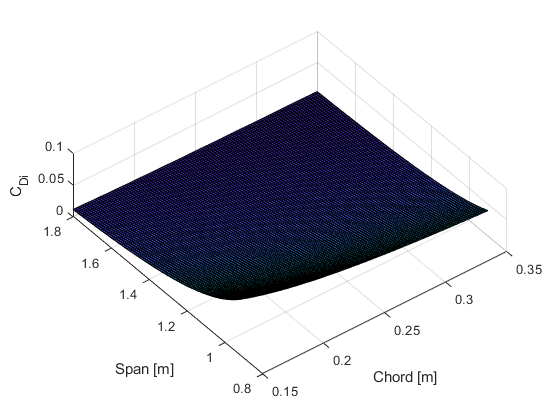

surf(c, b, C_Di)
ylabel('Span [m]')
xlabel('Chord [m]')
zlabel('C_{Di}')

This result clearly shows both chord and span should both be maximised to minimise induced drag